clear all
close all
clc



addpath("/Users/Jameskyle/Desktop/CMU/24-775 Bioinspired Robot Design and Experimentation/AcroBOT/Dynamics_HW12/Hardware Data");

fileName = "Hardware Data/EXP_SML"

fileName = "Hardware Data/EXP_SML"

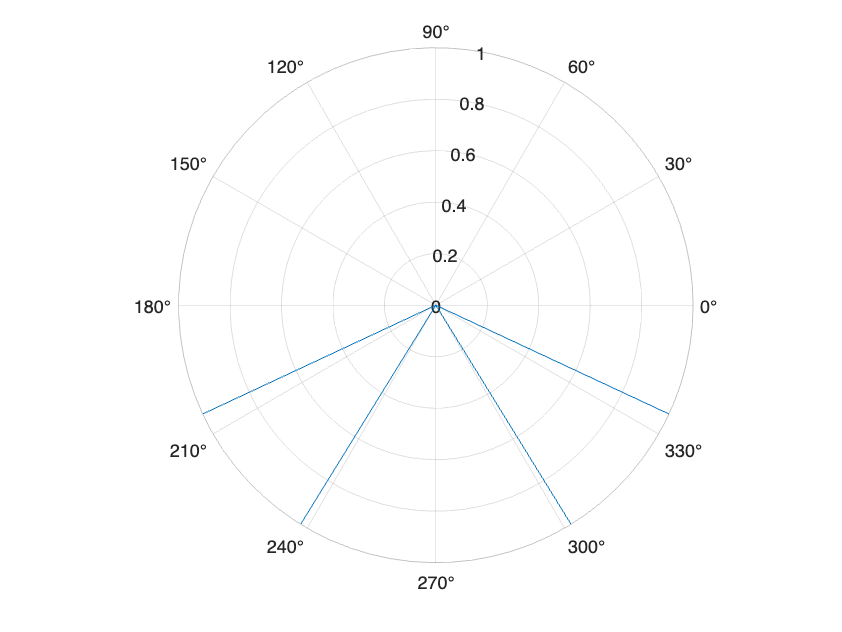



data = readmatrix(fileName,"NumHeaderLines",2);

alpha = data(1,1);
beta = data(1,2);
gamma = data(1,3);
% 
alpha = 45;
beta = 245;
gamma = 33.3;

arch_region = [beta; beta - gamma] + 90;
hollow_region = [90 + (270-beta+gamma); 90 + (270 - beta)] + 90;

figure();
polarplot([0 hollow_region(1)*pi/180 ...
    0 hollow_region(2)*pi/180 ...
    0 arch_region(1)*pi/180 ...
    0 arch_region(2)*pi/180],[0 1 0 1 0 1 0 1])

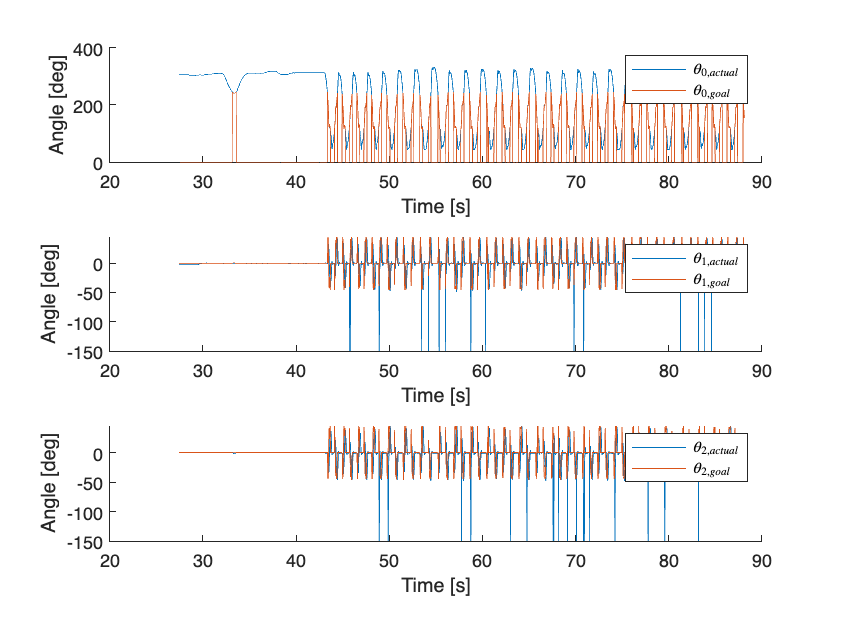



data = readmatrix(fileName,"NumHeaderLines",5);

time = data(:,1);
th0_actual = data(:,2);
th0_goal = data(:,3);
th1_actual = data(:,4);
th1_goal = data(:,5);
th2_actual = data(:,6);
th2_goal = data(:,7);
current = data(:,8);


figure();
subplot(3,1,1);
hold on;
plot(time,th0_actual,"DisplayName","$\theta_{0,actual}$");
plot(time,th0_goal,"DisplayName","$\theta_{0,goal}$");
hold off;
legend("Interpreter","latex");
ylabel("Angle [deg]");
xlabel("Time [s]");

subplot(3,1,2);
hold on;
plot(time,th1_actual,"DisplayName","$\theta_{1,actual}$");
plot(time,th1_goal,"DisplayName","$\theta_{1,goal}$");
hold off;
legend("Interpreter","latex");
ylabel("Angle [deg]");
xlabel("Time [s]");

subplot(3,1,3);
hold on;
plot(time,th2_actual,"DisplayName","$\theta_{2,actual}$");
plot(time,th2_goal,"DisplayName","$\theta_{2,goal}$");
hold off;
legend("Interpreter","latex");
ylabel("Angle [deg]");
xlabel("Time [s]");

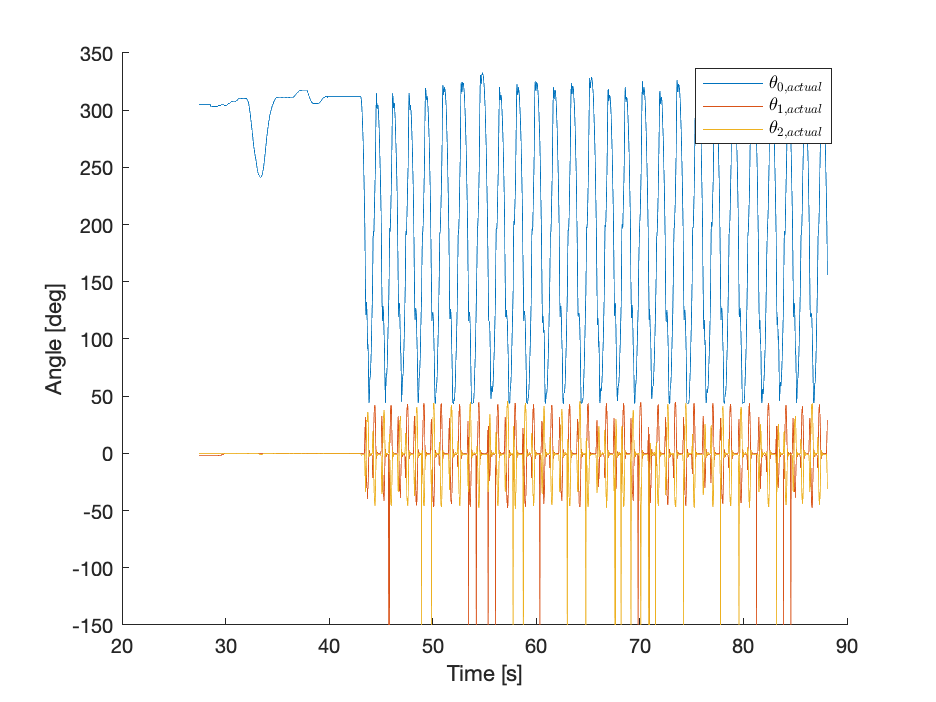




figure();
hold on;
plot(time,th0_actual,"DisplayName","$\theta_{0,actual}$");
plot(time,th1_actual,"DisplayName","$\theta_{1,actual}$");
plot(time,th2_actual,"DisplayName","$\theta_{2,actual}$");
hold off;
legend("Interpreter","latex");
ylabel("Angle [deg]");
xlabel("Time [s]");

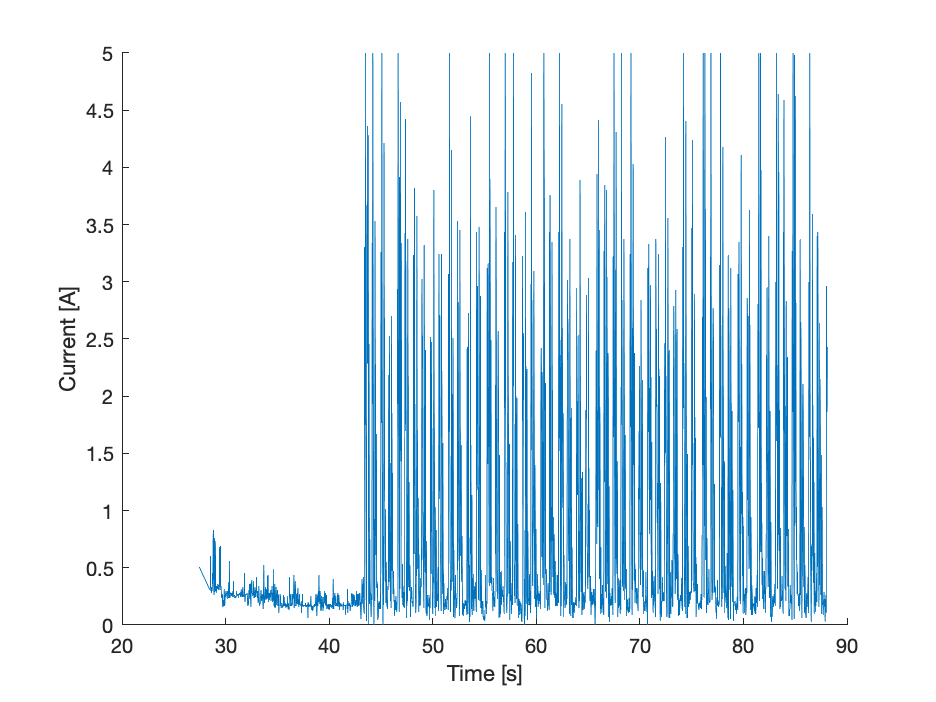



figure();
hold on;
plot(time,current,"DisplayName","$Current$");
hold off;
% legend("Interpreter","latex");
ylabel("Current [A]");
xlabel("Time [s]");

Max height:

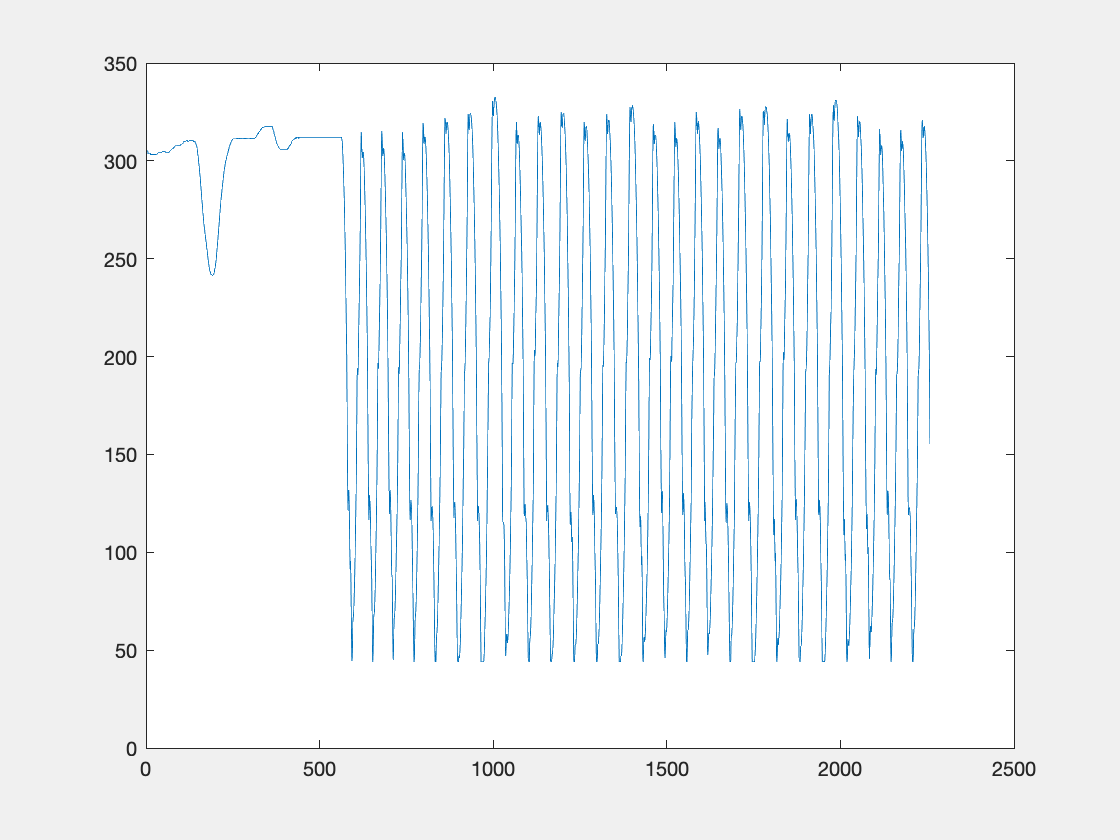

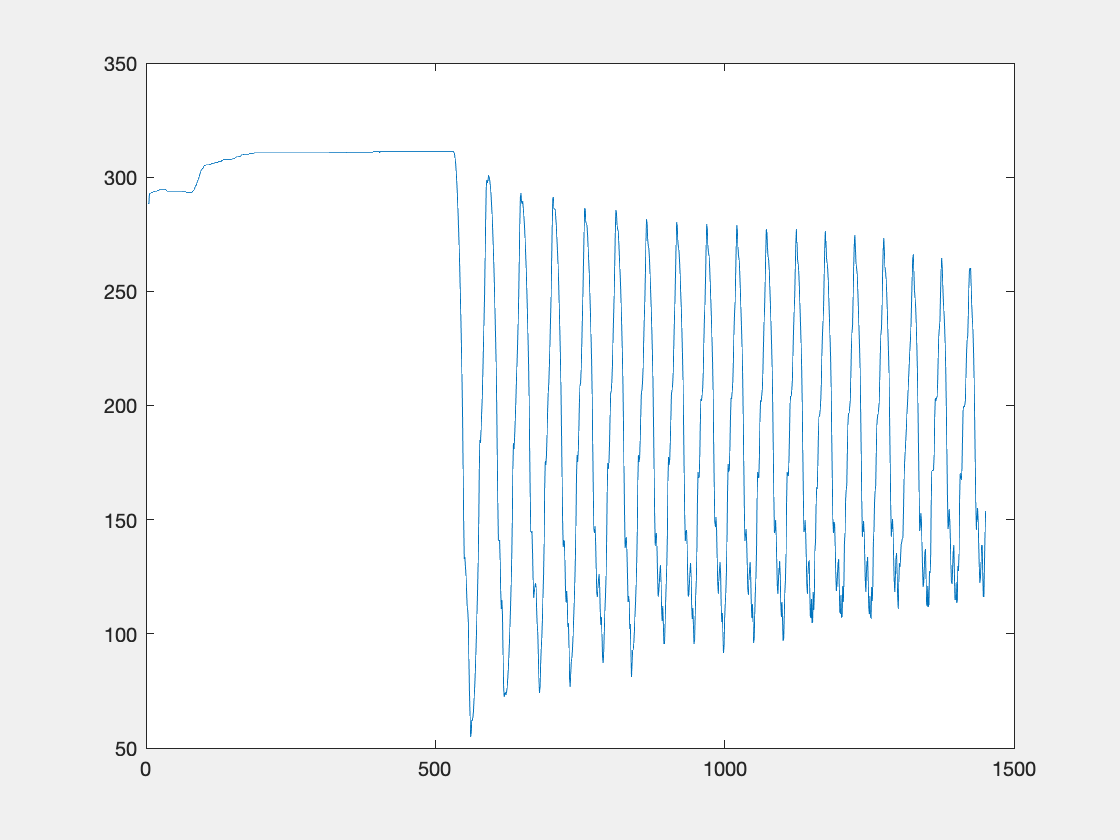

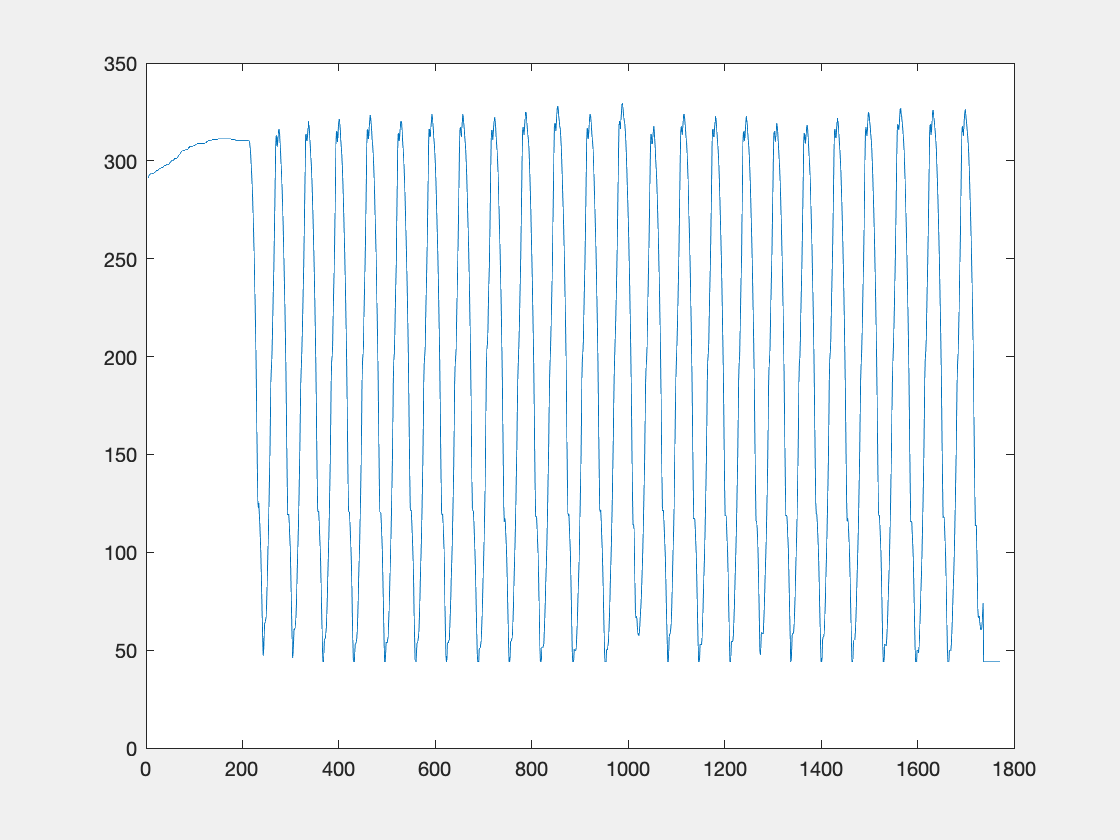

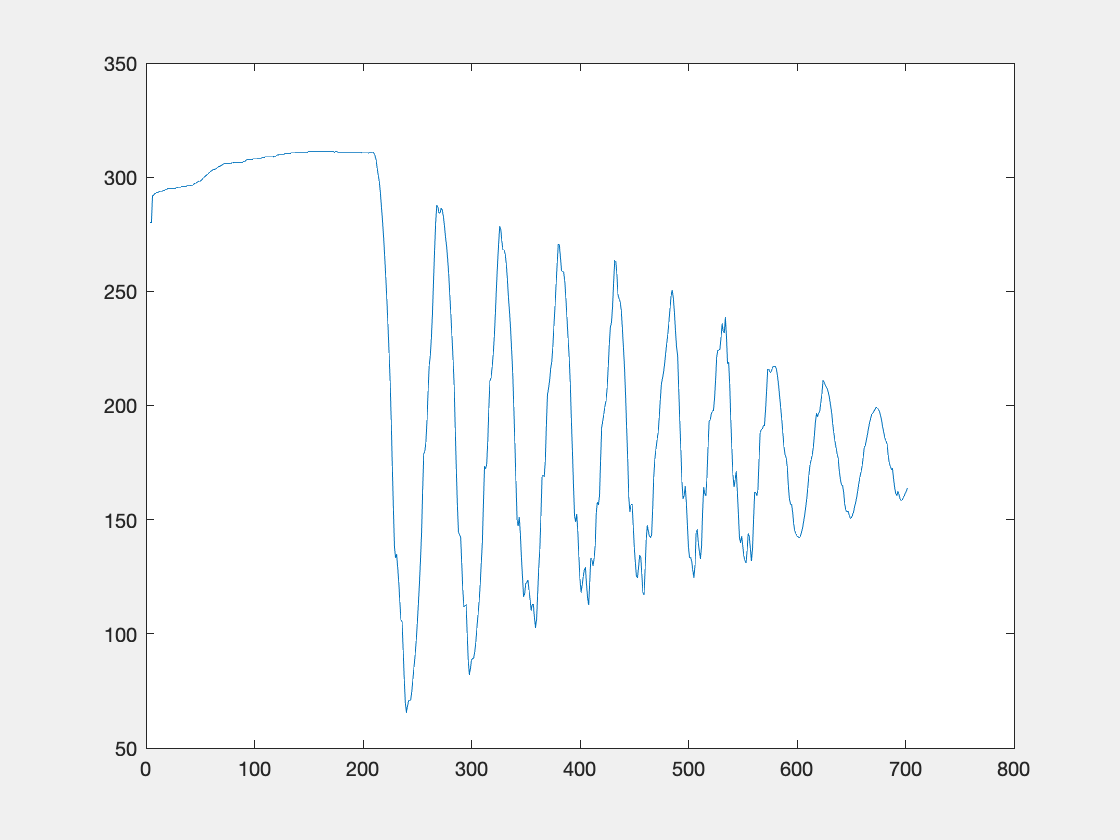

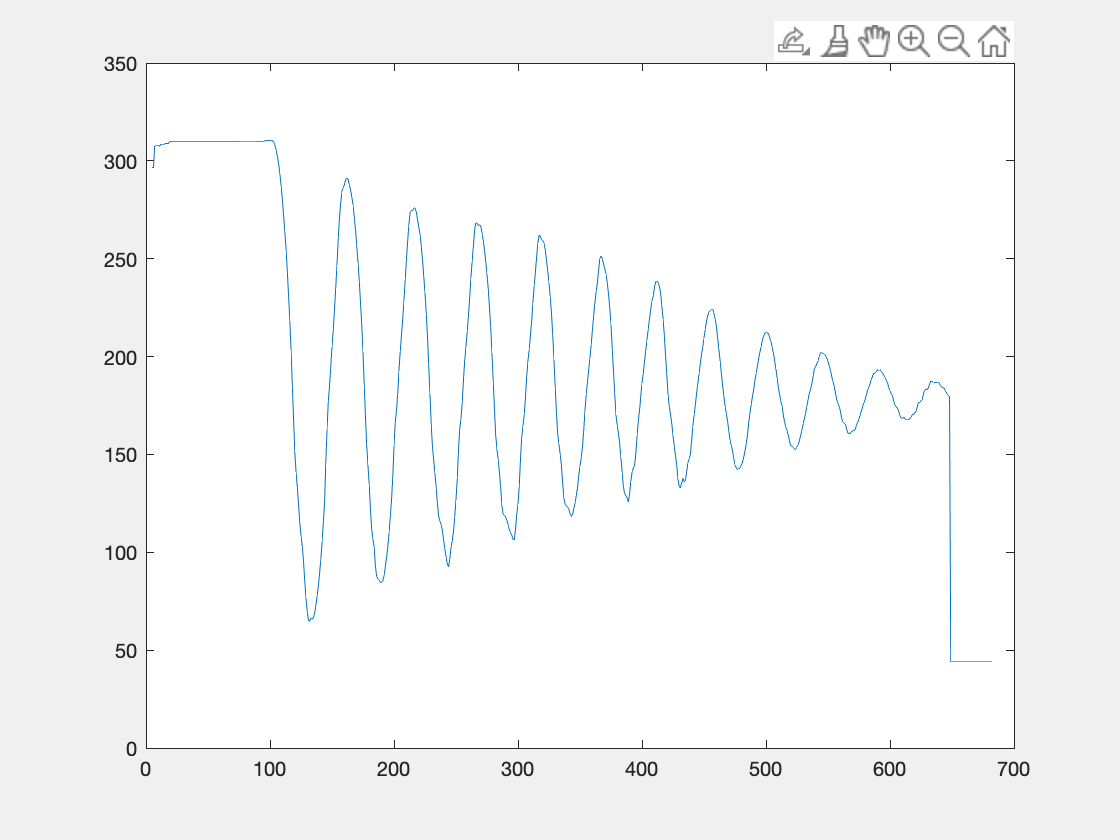

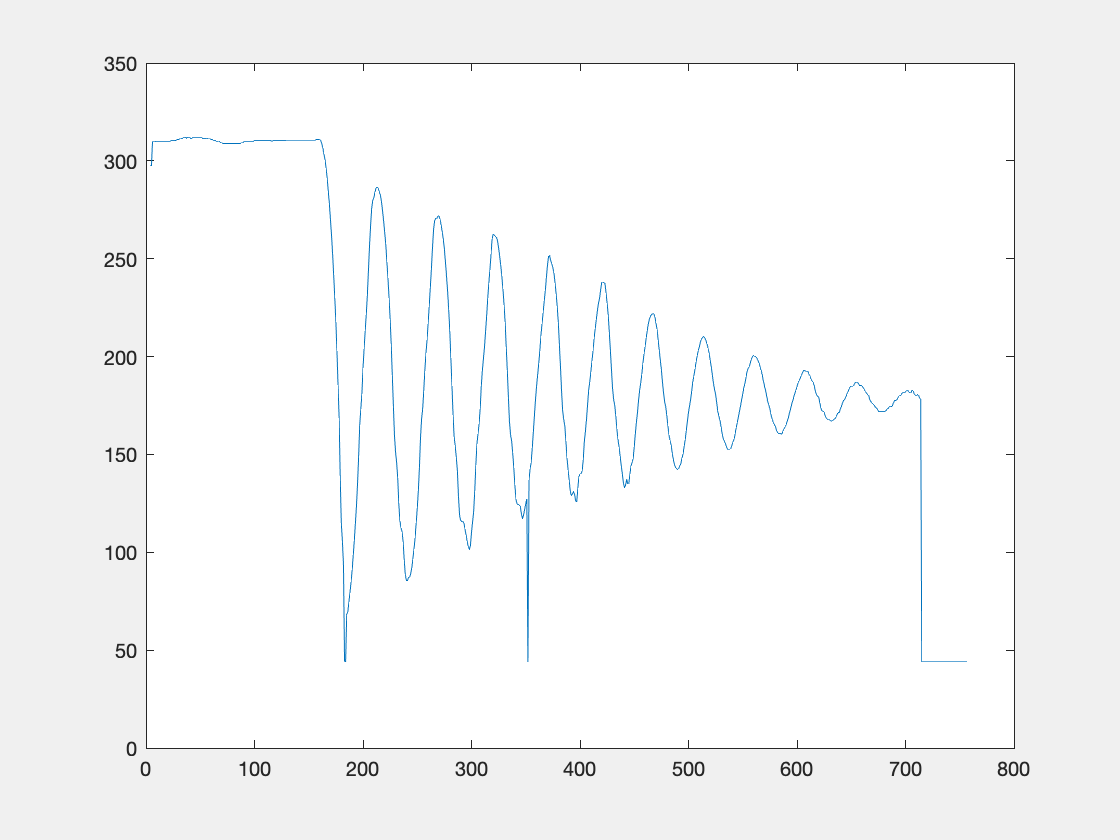


folderName = "Hardware Data/";
fileName = ["EXP_SML","EXP_SLM","EXP_MSL","EXP_MLS","EXP_LMS","EXP_LSM"];

n = length(fileName);

c = [1 2 3; 1 3 2; 2 1 3; 2 3 1; 3 2 1; 3 1 2];

alpha = zeros(n,1);
beta = zeros(n,1);
gamma = zeros(n,1);


for i = 1:length(fileName)

    data = readmatrix(folderName + fileName(i),"NumHeaderLines",2);

    alpha(i) = data(1,1);
    beta(i) = data(1,2);
    gamma(i) = data(1,3);
end

time = cell(n);
th0_actual = cell(n);
th0_goal = cell(n);
th1_actual = cell(n);
th1_goal = cell(n);
th2_actual = cell(n);
th2_goal = cell(n);
current = cell(n);

maxAngle = zeros(n,1);

for i = 1:length(fileName)

    data = readmatrix(folderName + fileName(i),"NumHeaderLines",2);
    
    currTime = data(:,1);
    currData = data(:,2);

    figure();
    plot(currData);
    [start,y] = ginput(1);

    time{i} = data(start:end,1);
    th0_actual{i} = data(start:end,2);
    th0_goal{i} = data(start:end,3);
    th1_actual{i} = data(start:end,4);
    th1_goal{i} = data(start:end,5);
    th2_actual{i} = data(start:end,6);
    th2_goal{i} = data(start:end,7);
    current{i} = data(start:end,8);

    maxAngle(i) = max(th0_actual{i});

end

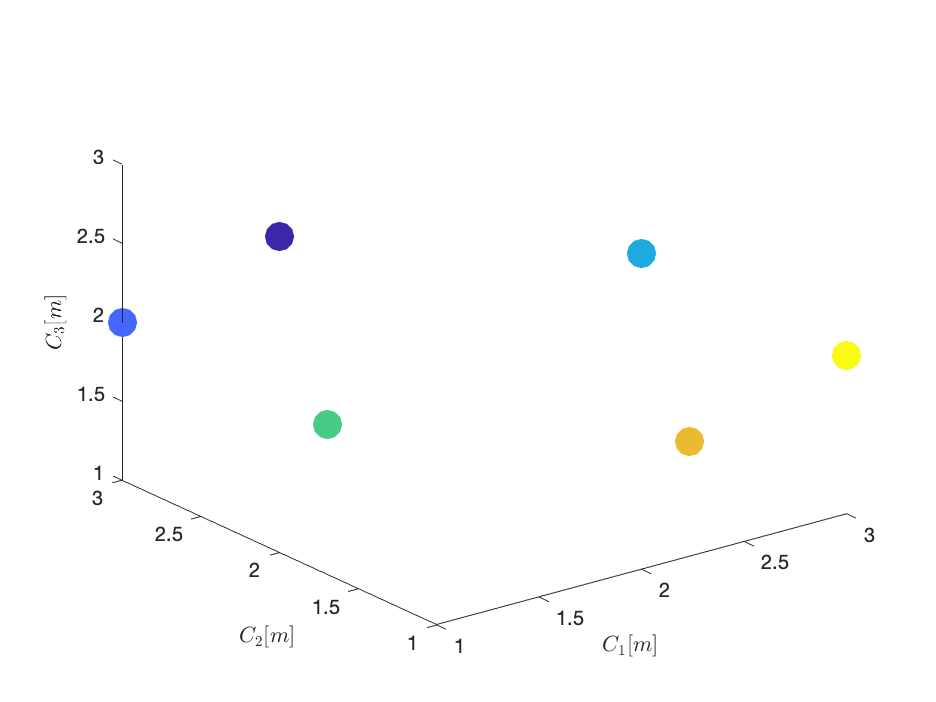


colorSort = [maxAngle c parula(n)];
colorSort = sortrows(colorSort,1,'ascend');

figure();
hold on;
maxHeight = max(maxAngle);
minHeight = min(maxAngle);
range = maxHeight - minHeight;
for i = 1:n
    plot3(colorSort(i,2),colorSort(i,3),colorSort(i,4),'.','MarkerSize',50,'Color',colorSort(i,5:7));
end
hold off;
view(3)
xlabel('$C_1 [m]$','interpreter','latex');
ylabel('$C_2 [m]$','interpreter','latex');
zlabel('$C_3 [m]$','interpreter','latex');
colormap('parula');